# MATLAB for Business Analytics: Forecasting, Optimization, and AI Agents

You will not need to write algorithms from scratch today.

Every technique here is a single MATLAB function or app - your job is to interpret what it tells you about the business, the same way you would read output from Excel, Power BI, or SPSS.

We follow one fictional retailer, **Brighten Up Mart**, through three connected decisions that any retail, logistics, or supply-chain manager faces every month.

- **Part 1 - Machine Learning for Forecasting:** how much will customers buy next quarter?

- **Part 2 - Transportation Optimization:** given that demand, what is the cheapest way to ship inventory to stores?

- **Part 3 - AI Agentics for Data Analytics and Dashboard Intelligence:** how do we turn all of this into a dashboard - and an assistant - that busy executives can actually use

## The Business Scenario

Brighten Up Mart is a Thai retail chain with three regional distribution centers and five stores.

Every month, the management team has to answer three questions: *How much will we sell?*, *How do we distribute stock at the lowest cost?*, and *How do we get answers fast, without waiting for an analyst?*

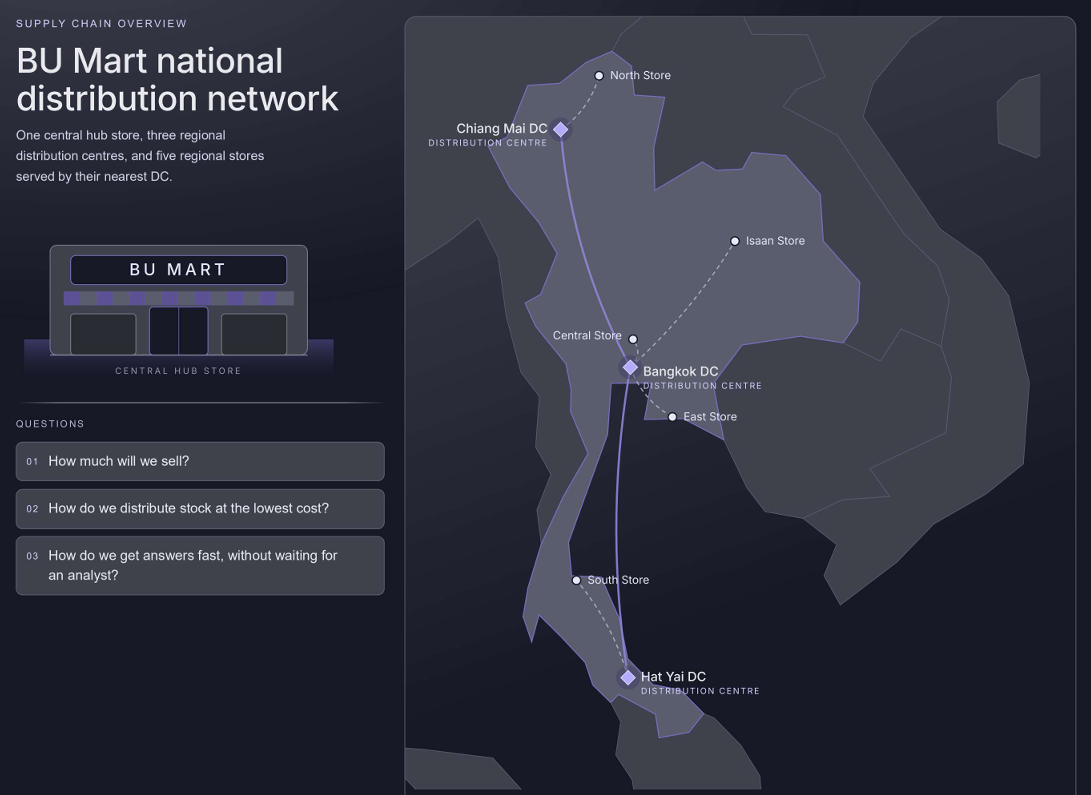

We start by loading four years of monthly sales history, together with the marketing budget spent each month - a common early-warning signal for demand.

Want summary of the data?

## A First Look at the Data

Before modeling anything, always plot the raw series.

### Try to find some correlation between data

### Plot unit sales in time

## Part 1: Machine Learning for Forecasting

Traditional forecasting rules ("this month equals the same month last year, plus a bit of growth") are simple but blind to anything unusual, such as a bigger-than-usual marketing push.

Machine learning takes a different approach: show the computer many historical examples - the month of the year, last month's sales, the same month a year ago, and the marketing budget - and let it learn the relationship on its own.

It is the same underlying idea used in product recommendations and credit-risk scoring, applied here to demand instead.

### Turning History into Learning Examples

A machine learning model needs the problem framed as *features in, sales out*.

We build one row per month containing the calendar month, last month's sales, the same month one year prior, and the marketing spend planned for that month - then hold out the most recent six months to test the model honestly, on data it has never seen.

### Prepare train data

make the first 2 years as the train data and the 3rd year as the test data

BUS_train =
BUS_test =

### Training the Model by Regression Learner App

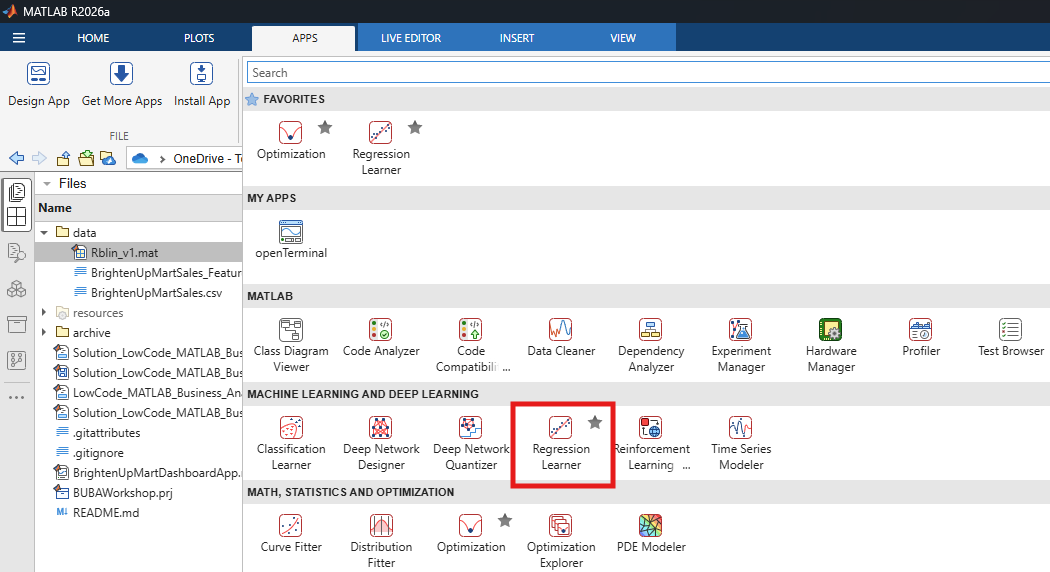

% or open it in by type "regressionLearner" in code

% regressionLearner %% uncomment this and run to call the app

### Explain Model Predictions

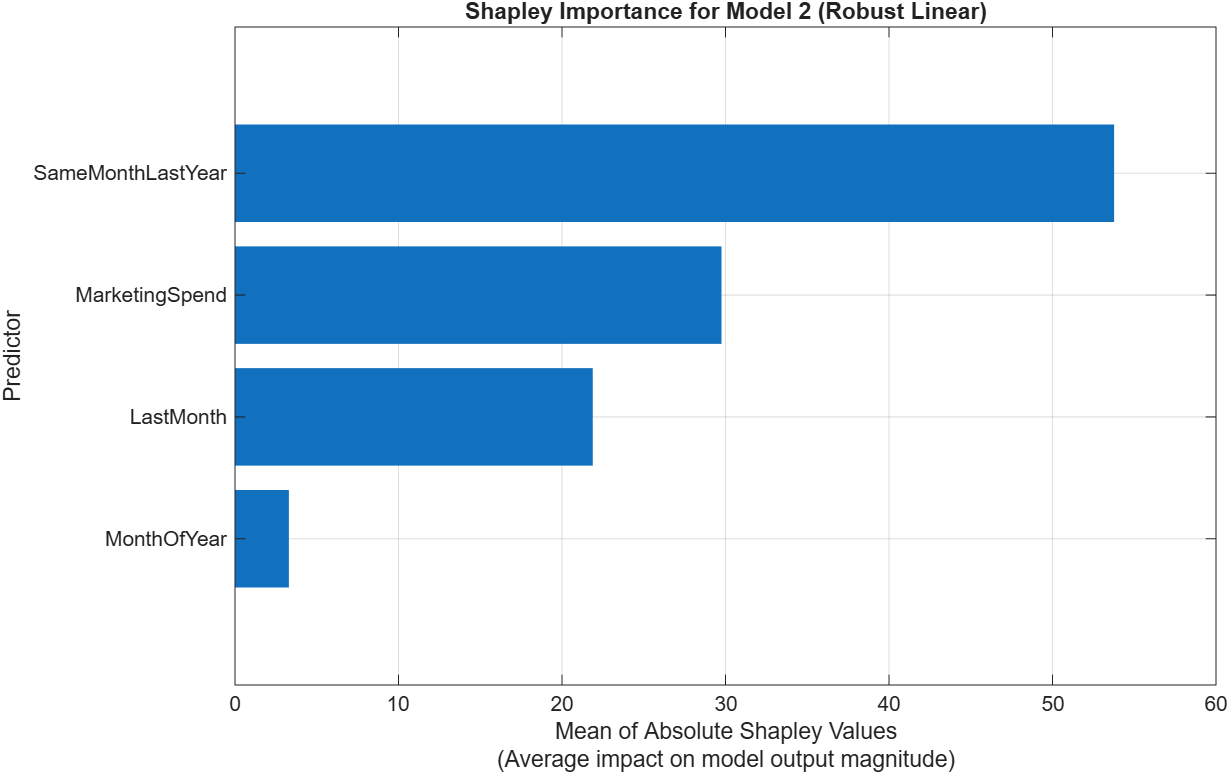

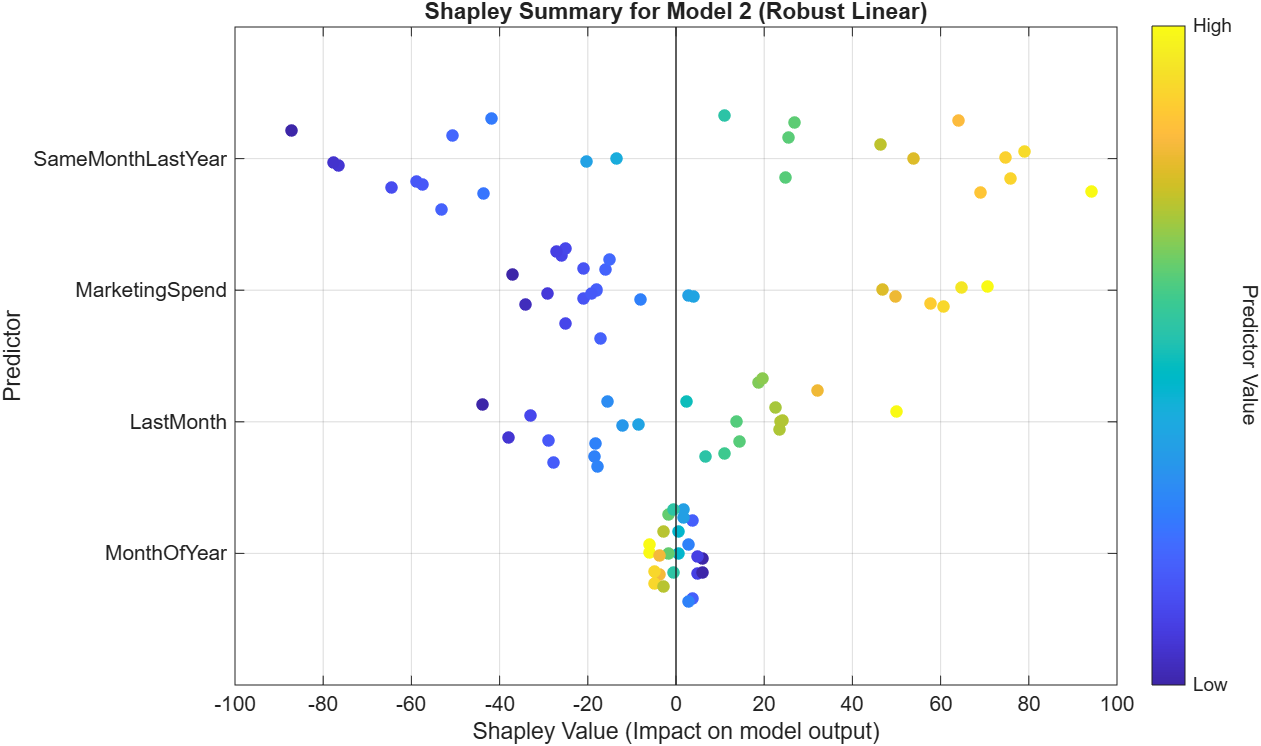

### Forecast the 3rd year sales

prepare the input table

input =

prediction

forecast3rdYrSales = ;

date array for plotting

m = BUS.Month(37:end);

compare the result

### Forecasting

With the approach validated, we retrain on the full history and roll the model forward, feeding each prediction back in as next month's "last month" value.

As shown earlier, the input needed for forecasting are

- Month of Year ( i.e. 1 for Jan, 2 for Feb)

- Last Month Sales

- Same Month Last Year Sales

- Marketing Spend

Let's go step by step. Starting with forecast the upcoming month

#### Step-by-Step Forecasting

create needed input one by one

assign next month value

nextMonth = 

access last month sales

lastMonthSales = 

access same month last year sales

sameMonthLastYearSales = 

assign marketing spend

marketSpend = 42

put all of them in a table

input = table(nextMonth,lastMonthSales,sameMonthLastYearSales,marketSpend, ...
    'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend'})

predict the next month sales

nextMonthSales = 

Now, do the same for next month (2), but the last month data is` nextMonthSales`

Repeat the process until the desired duration is met. Easy? What if we want 50-years data?

#### Loop for Forecasting

targetm = 6; % forecast the next 6 months
focusmkt = 4; % boost marketing spend on April
[futureDates, plannedSpend, forecastSales] = createForecast(BUS, targetm, focusmkt, 'RbLin');
forecastTbl = table(futureDates, round(forecastSales), plannedSpend, ...
    'VariableNames', {'Month','ForecastSales','PlannedMarketingSpend'})

### Plotting the Forecast

The forecast picks up right where history ends, and clearly shows the expected April demand spike from the planned promotion - exactly the kind of signal that feeds into Part 2.

## Part 2: Transportation Optimization

Forecasting tells us Brighten Up Mart needs to move about 948 units in April.

The next business question is purely operational: given three distribution centers with limited capacity and five stores that must each receive their share, which shipping routes should we use to meet every store's demand at the lowest possible total shipping cost?

This is the classic *transportation problem*, and it is a perfect example of business **optimization**: instead of trying options by hand in a spreadsheet, we let MATLAB search every feasible shipping plan and return the mathematically cheapest one.

### Setting Up the Distribution Network

Each distribution center (DC) has a maximum monthly capacity, each store has a demand it must receive in full, and shipping a unit costs a different amount on every route depending on distance.

#### Import Shipping cost

convert table to array

#### Import Supply Share

assign DC names and  DC share

dcNames = 
dcShare = 

#### Import Demand Share

assign store names and store share

storeNames = 
storeShare = 

assign total demand from forecast data on the focus marketing month, then calculate total supply from total demand

totalDemand = round(forecastTbl.ForecastSales(focusmkt))
totalSupply = ceil(totalDemand*1.03)

calculate store demand from total demand and store share

demand = round(totalDemand*storeShare);
% make the summation of store demand equal to total demand
demand(end) = demand(end) + (totalDemand - sum(demand)); 
demand

calculate DC supply from total supply and DC share

supply = round(totalSupply*dcShare);
% make the summation of DC supply equal to total supply
supply(1) = supply(1) + (totalSupply - sum(supply));
supply

### Solving for the Least-Cost Shipping Plan by Optimize Task

Optimize Task lets us describe the decision in business terms: choose how many units to ship on each route so that no DC ships more than its capacity, every store's demand is fully met, and total shipping cost is as low as possible.

MATLAB hands this off to a linear-programming solver, which is guaranteed to find the mathematically optimal plan - not just a good one.

Display the optimized solution

string(month(forecastTbl.Month(focusmkt),'name'))
shipTbl = array2table(round(solution.shipUnit), 'VariableNames', storeNames, 'RowNames', dcNames)
totalCost = sum(sum(shipCost .* solution.shipUnit))

### How Much Did Optimization Save?

To show the value of optimization, we compare it against a common real-world habit: allocating stock first-come, first-served, store by store, without considering cost at all.

[alloc, naiveCost, savings] = naiveAllocation(supply, demand, shipCost, totalCost, ...
                                                forecastTbl, focusmkt);

Optimization saves BrightMart roughly 1M THB on this single month's shipment simply by choosing routes more intelligently, with no change to demand, supply, or prices.

## Part 3: AI Agentics for Data Analytics and Dashboard Intelligence

A forecast and an optimal shipping plan are only useful if the right people see them in time to act.

This final part covers two layers of *Business Intelligence*: a visual **dashboard** that summarizes everything at a glance, and an early look at **AI agents** - software that can take a plain-language business question and route it to the right analysis automatically, the idea behind AI copilots now appearing inside tools like Power BI and Tableau.

open BrightenUpMartDashboardApp.mlapp

## Appendix

If you would like to know how to make the features table from scratch

lag1 = [NaN; BUS.Sales(1:end-1)];
lag12 = [NaN(12,1); BUS.Sales(1:end-12)];
featTbl = table(month(BUS.Month), lag1, lag12, BUS.MarketingSpend, BUS.Sales,...
    'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend','Sales'});
featTbl = featTbl(13:end,:);
featTbl
clear lag1 lag12 featTbl 

createForecast function

function [futureDates, plannedSpend, forecastSales] = createForecast(BUS, targetm, focusmkt, model)
%CREATEFORECAST Create future dates, planned marketing spend, and forecasts

    % Resolve model input: struct or name in base workspace
    if ischar(model) || (isstring(model) && isscalar(model))
        modelName = char(model);
        model = evalin('base', modelName);
    end
    if ~isstruct(model) || ~isfield(model,'predictFcn')
        error('createForecast:InvalidModel', 'model must be a struct with a predictFcn field.');
    end

    monthIdx = 1:targetm;                             % create index from defined target m
    futureDates = BUS.Month(end) + calmonths(monthIdx)'; % create futureDates for forecasting
    
    rng(7);                                           % fix random seed
    % randomized planned marketing spend
    plannedSpend = poissrnd(median(BUS.MarketingSpend(end-12:end)), [targetm,1]);
     % assign spike marketing spend
    plannedSpend(focusmkt) = round(median(BUS.MarketingSpend(end-12:end)) ...
                    + 2*std(BUS.MarketingSpend(end-12:end)));
    
    forecastSales = zeros(targetm,1);                 % allocate array for forecastSales
    lag1cur = BUS.Sales(end);                         % last month sales
    for h = monthIdx
        row = table(h, lag1cur, BUS.Sales(end-12+h), plannedSpend(h), ...
            'VariableNames', {'MonthOfYear','LastMonth','SameMonthLastYear','MarketingSpend'});
        forecastSales(h) = model.predictFcn(row);
        lag1cur = forecastSales(h);
    end

end

Naive cost calculation and plot

function [alloc, naiveCost, savings] = naiveAllocation(supply, demand, cost, totalCost, ...
                                                                        forecastTbl, focusmkt)
%NAIVEALLOCATION Compute a greedy (naive) allocation, cost, savings and plot
%   [alloc, naiveCost, savings] = naiveAllocation(supply, demand, cost, totalCost,
%                                                               forecastTbl, focusmkt)
%   supply : vector of supply by distribution center (nx1)
%   demand : vector of demand by store (1xm or mx1)
%   cost   : nxm cost matrix (same size as allocation)
%   totalCost : optimized total cost (scalar) for comparison
%   forecastTbl, focusmkt : used to label the plot

supply = supply(:);                 % ensure column
demand = demand(:)';                % ensure row
n = numel(supply);
m = numel(demand);
remaining = supply;
alloc = zeros(n,m);

for j = 1:m
    d = demand(j);
    for i = 1:n
        take = min(remaining(i), d);
        alloc(i,j) = take;
        remaining(i) = remaining(i) - take;
        d = d - take;
        if d <= 0
            break
        end
    end
end

naiveCost = sum(sum(cost .* alloc));
savings = naiveCost - totalCost;

% Plot comparison
figure;
bar(categorical({'Naive Allocation','MATLAB-Optimized'}), [naiveCost totalCost]);
ylabel('Total Shipping Cost (THB)');
title({
    sprintf('Optimization Impact: %s Distribution Plan', ...
            string(month(forecastTbl.Month(focusmkt),'name'))), ...
    sprintf('Savings: %0.0f THB', savings)
});

end